## Step 0: Initialization

clear;

rate = 48000; % sampling rate

% A chirp signal of 1 second
% with a freq range of [1, 18]kHz 
x = audioread('chirp.wav');

% 6 reference data of 2 seconds
% 1 ~ 2: on a bed
% 3 ~ 4: on a desk
% 5 ~ 6: on a table
load('ref.mat') 

load('test.mat') % 3 reference data of 2 seconds

## Step 1-1: Feature extraction 1: matched filter (xcorr)

figure
for i = 1:length(ref)
    ref(i).xcorr = conv(flipud(x), ...
        ref(i).raw);
end

for i = 1:length(test)
    test(i).xcorr = conv(flipud(x), ...
        test(i).raw);
end

distanceLimit = 1; % unit: m
speed = 340; % m/s
sampleLimit = ceil(distanceLimit / speed ...
   * rate);

margin = 0.001 * rate;

for i = 1:length(ref)
    [~, idx] = max(abs(ref(i).xcorr));
    ref(i).xcorr(idx + sampleLimit:end) ...
        = [];
    ref(i).xcorr(1:idx - margin) = [];
end

for i = 1:length(test)
    [~, idx] = max(abs(test(i).xcorr));
    test(i).xcorr(idx + sampleLimit:end) ...
        = [];
    test(i).xcorr(1:idx - margin) = [];
end

## Step 1-2: Feature extraction 2: acoustic spectrum (fft)

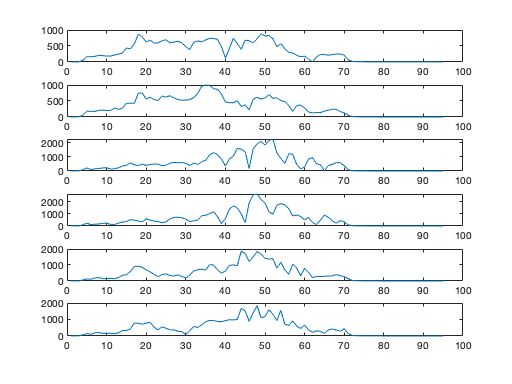

figure
for i = 1:length(ref)
    ref(i).spectrum = abs(fft(ref(i).xcorr));
    ref(i).spectrum = ref(i).spectrum(...
        2:ceil(length(ref(i).spectrum) / 2 + 1));
    
    subplot(length(ref), 1, i)
    plot(ref(i).spectrum)
end

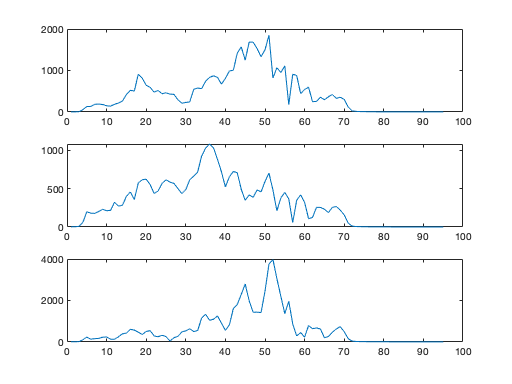


figure
for i = 1:length(test)
    test(i).spectrum = abs(fft(test(i).xcorr));
    test(i).spectrum = test(i).spectrum(...
        2:ceil(length(test(i).spectrum) / 2 + 1));
    subplot(length(test), 1, i)
    plot(test(i).spectrum)
end

## Step 2: Classification (simply corr-based 1NN)

cur = test(3).spectrum;

corrVal = [];
for i = 1:length(ref)
    corrVal(i) = corr(cur', ...
        ref(i).spectrum');
end

disp(corrVal)

  1 ~ 3번 열

    0.6167    0.5160    0.8592

  4 ~ 6번 열

    0.6997    0.8000    0.8295




[~, idx] = max(corrVal);
disp(ref(idx).label)

desk
